Beta Distribution

PDF is between 0 and 1 - useful for parameters such as volume fractions?

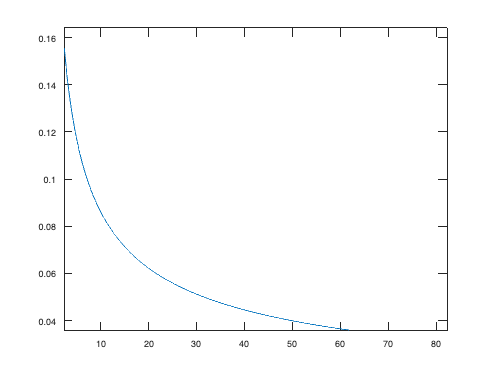

mu = 0.9 ;

As = [1:0.1:1000] ;
var = zeros(size(As)) ;

for iA = 1:length(As)
    A = As(iA) ;
    B = (A/mu)-A ;
    v = A+B ;

    var(iA) = mu*(1-mu) / (1+v) ;
end

figure
plot(As,sqrt(var))